## **Prepare images for training and testing**

Create datastore for the images with folder names as labels

imds = imageDatastore("Images","IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore with properties:

                       Files: {
                              ' ...\SportsBalls\Images\Baseball\071119.S.WCT.Baseball stock art.jpg';
                              ' ...\SportsBalls\Images\Baseball\Baseball_(crop).jpg';
                              ' ...\MATLAB\deeplearning_course_files\SportsBalls\Images\Baseball\ball.jpg'
                               ... and 48 more
                              }
                      Labels: [Baseball; Baseball; Baseball ... and 48 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


Split images for training and testing

[trainim,testim] = splitEachLabel(imds,0.6)

trainim =   ImageDatastore with properties:

                       Files: {
                              ' ...\SportsBalls\Images\Baseball\071119.S.WCT.Baseball stock art.jpg';
                              ' ...\SportsBalls\Images\Baseball\Baseball_(crop).jpg';
                              ' ...\MATLAB\deeplearning_course_files\SportsBalls\Images\Baseball\ball.jpg'
                               ... and 29 more
                              }
                      Labels: [Baseball; Baseball; Baseball ... and 29 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


testim =   ImageDatastore with properties:

                       Files: {
                              ' ...\SportsBalls\Images\Baseball\baseballwithbat-1600.jpg';
                              ' ...\SportsBalls\Images\Baseball\getty_482805043_185511.jpg';
                              ' ...\deeplearning_course_files\SportsBalls\Images\Baseball\images.jpg'
                               ... and 16 more
                              }
                      Labels: [Baseball; Baseball; Baseball ... and 16 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                     ReadFcn: @readDatastoreImage


trainds = augmentedImageDatastore([227 227],trainim,"ColorPreprocessing","gray2rgb")

trainds =   augmentedImageDatastore with properties:

             NumObservations: 32
                       Files: {32×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


testds = augmentedImageDatastore([227 227],testim,"ColorPreprocessing","gray2rgb")

testds =   augmentedImageDatastore with properties:

             NumObservations: 19
                       Files: {19×1 cell}
    AlternateFileSystemRoots: {}
               MiniBatchSize: 128
            DataAugmentation: 'none'
          ColorPreprocessing: 'gray2rgb'
                  OutputSize: [227 227]
              OutputSizeMode: 'resize'
        DispatchInBackground: 0


Determine number of ball types

numClasses = numel(categories(imds.Labels))

numClasses = 7

## Create network form AlexNet

net = alexnet

net =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'output'}


layers = net.Layers

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0

layers(end-2) = fullyConnectedLayer(numClasses)

layers =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0

layers(end) = classificationLayer

layers =   25x1 Layer array with layers:

     1   'data'    Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'   Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'   ReLU                          ReLU
     4   'norm1'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'   Grouped Convolution           2 groups of 128 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'   ReLU                          ReLU
     8   'norm2'   Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'   Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
 

## Training options

opts = trainingOptions("sgdm","InitialLearnRate",0.001)

opts =   TrainingOptionsSGDM with properties:

                     Momentum: 0.9000
             InitialLearnRate: 1.0000e-03
    LearnRateScheduleSettings: [1×1 struct]
             L2Regularization: 1.0000e-04
      GradientThresholdMethod: 'l2norm'
            GradientThreshold: Inf
                    MaxEpochs: 30
                MiniBatchSize: 128
                      Verbose: 1
             VerboseFrequency: 50
               ValidationData: []
          ValidationFrequency: 50
           ValidationPatience: Inf
                      Shuffle: 'once'
               CheckpointPath: ''
         ExecutionEnvironment: 'auto'
                   WorkerLoad: []
                    OutputFcn: []
                        Plots: 'none'
               SequenceLength: 'longest'
         SequencePaddingValue: 0
     SequencePaddingDirection: 'right'
         DispatchInBackground: 0
      ResetInputNormalizat

## Perform training

[sportnet,info] = trainNetwork(trainds,layers,opts)

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:03 |       12.50% |       5.2550 |          0.0010 |
|      30 |          30 |       00:01:58 |      100.00% |       0.0003 |          0.0010 |
|========================================================================================|


sportnet =   SeriesNetwork with properties:

         Layers: [25×1 nnet.cnn.layer.Layer]
     InputNames: {'data'}
    OutputNames: {'classoutput'}


info = struct with fields:
        TrainingLoss: [5.2550 2.3330 0.5393 0.3539 0.4791 0.1016 0.0575 0.1250 0.0168 0.0077 0.0563 0.0232 0.0094 0.0057 0.0022 0.0017 0.0015 0.0162 0.0274 0.0053 0.0024 5.0671e-04 0.0109 0.0016 7.6141e-04 0.0903 0.0011 0.0070 5.1353e-05 2.6986e-04]
    TrainingAccuracy: [12.5000 46.8750 81.2500 84.3750 81.2500 93.7500 96.8750 96.8750 100 100 96.8750 100 100 100 100 100 100 100 96.8750 100 100 100 100 100 100 96.8750 100 100 100 100]
       BaseLearnRate: [0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010 0.0010]


## Test network with test images

preds = classify(sportnet,testds)

preds = 19×1 categorical array
     Baseball 
     Golfball 
     Baseball 
     Basketball 
     Basketball 
     Baseball 
     Football 
     Football 
     Golfball 
     Soccerball 
     Soccerball 
     Volleyball 
     Soccerball 
     Tennisball 
     Tennisball 
     Tennisball 
     Volleyball 
     Volleyball 
     Volleyball 


find misclassification rate

mis = sum(preds~=testim.Labels)/numel(preds)

mis = 0.2105

visualize confusion matrix

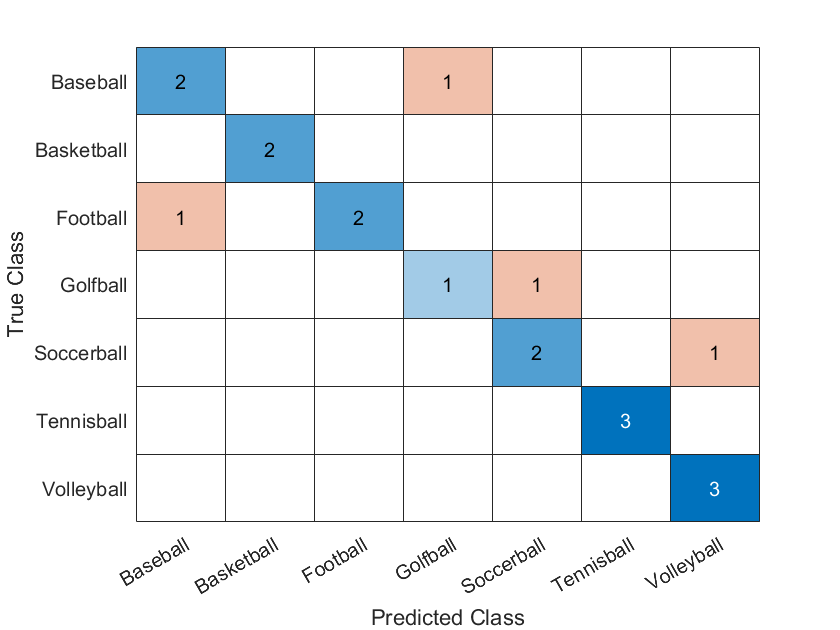

ans =   ConfusionMatrixChart with properties:

    NormalizedValues: [7×7 double]
         ClassLabels: [7×1 categorical]

  Show all properties


confusionchart(testim.Labels,preds)